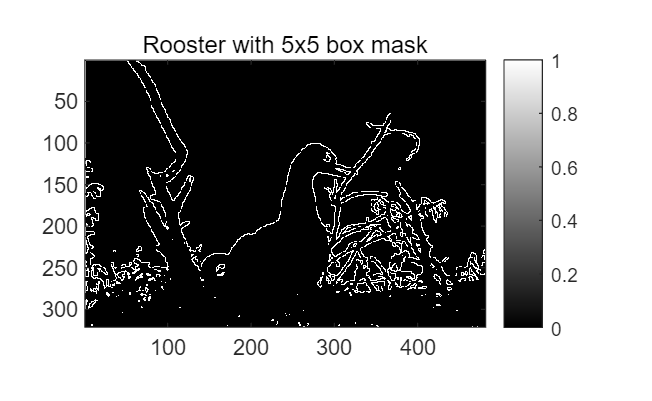

%Load images
I1=imread('im1.jpg');

% Convert colour images to grayscale
I1g = im2gray(I1);

% Convert all images from integer format to double format
Iagd = im2double(I1g);
Iad = im2double(I1);
%color conponent



Iabox5 = BY(Iad);
Iabox5 = Dog(Iabox5);



figure(1), clf; colormap("gray")
subplot(1,1,1), imagesc(Iabox5); axis('equal','tight'); 
colorbar, title("Rooster with 5x5 box mask")

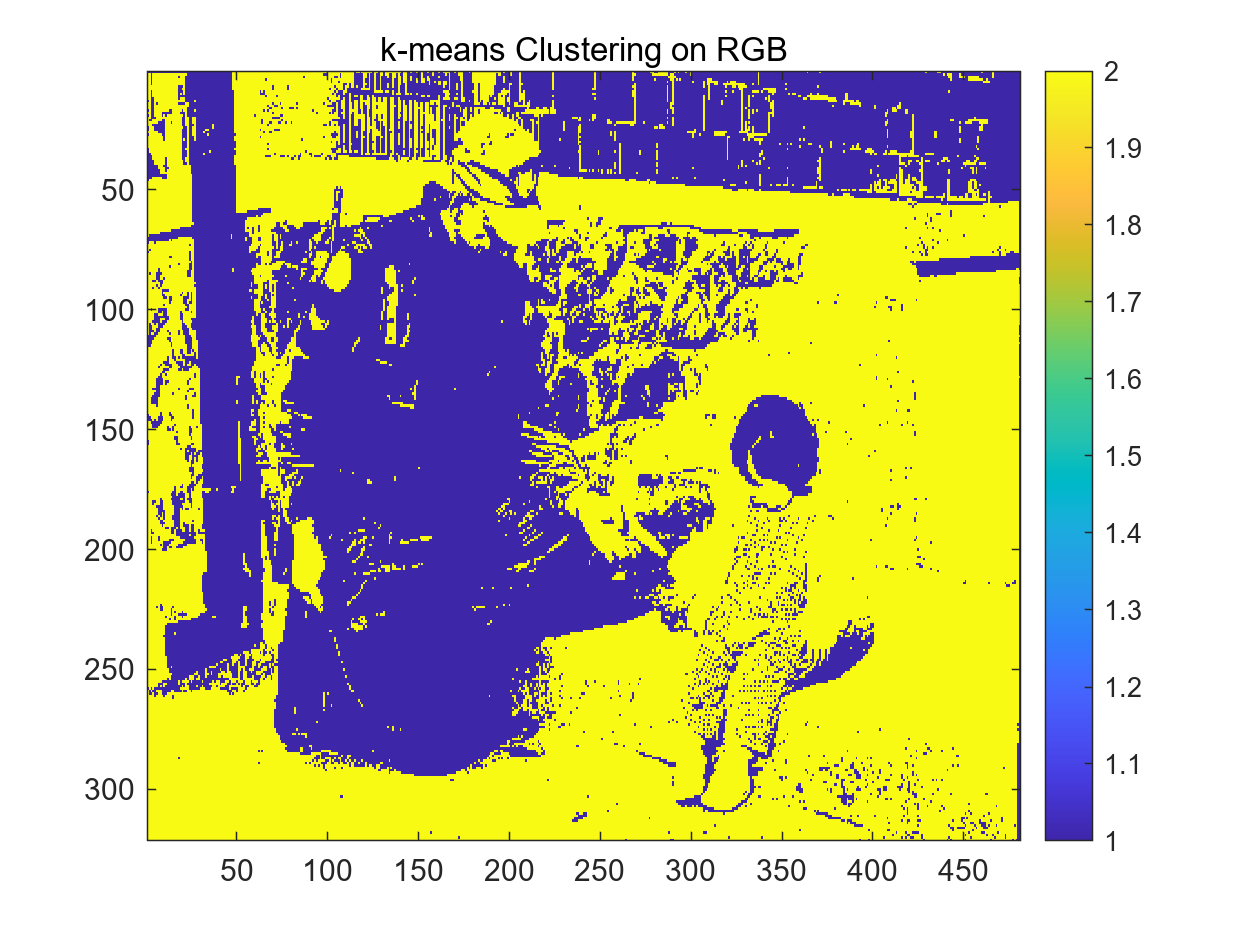

I1=imread('im2.jpg');

figure, colormap('default')
I1=imsegkmeans(I1,2);
imagesc(I1); colorbar; title('k-means Clustering on RGB')

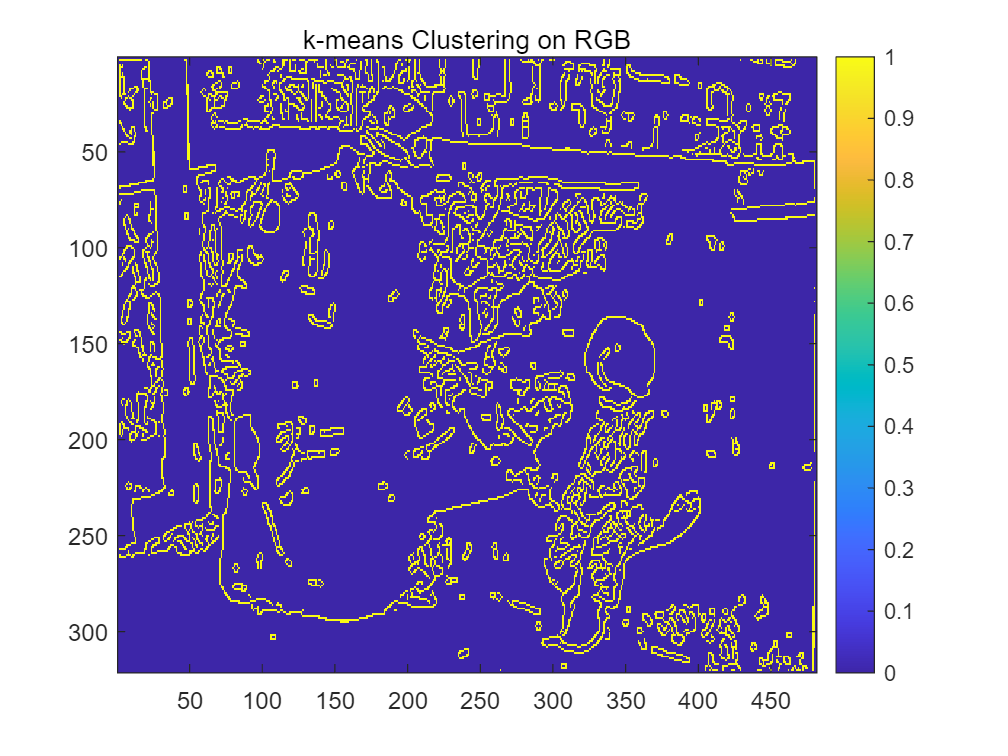

I1 = im2gray(I1);
I1 = Can(I1);
imagesc(I1); colorbar; title('k-means Clustering on RGB')

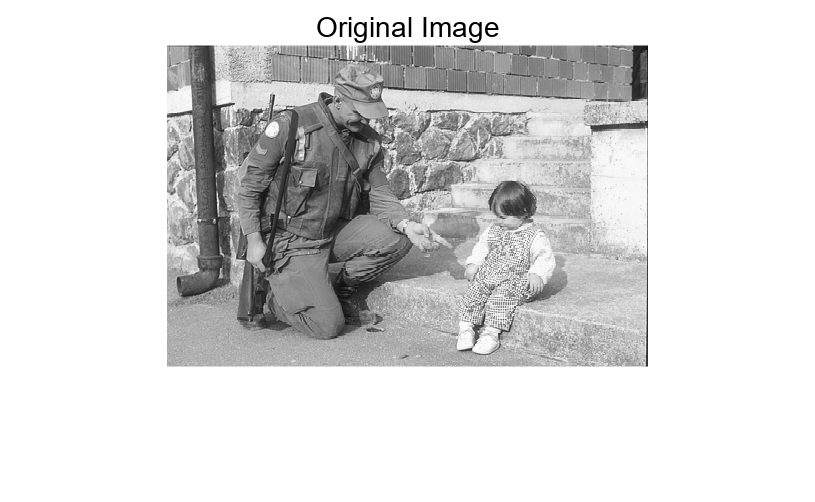

%%使用主动轮廓分割图像%%
close all;                  %关闭当前所有图形窗口，清除工作空间所有变量
clear all;
clc;
%%读取并显示灰度图像
I = imread('im2.jpg');%读取图像
I = im2gray(I);
figure,imshow(I)%显示图像
title('Original Image')%添加标签

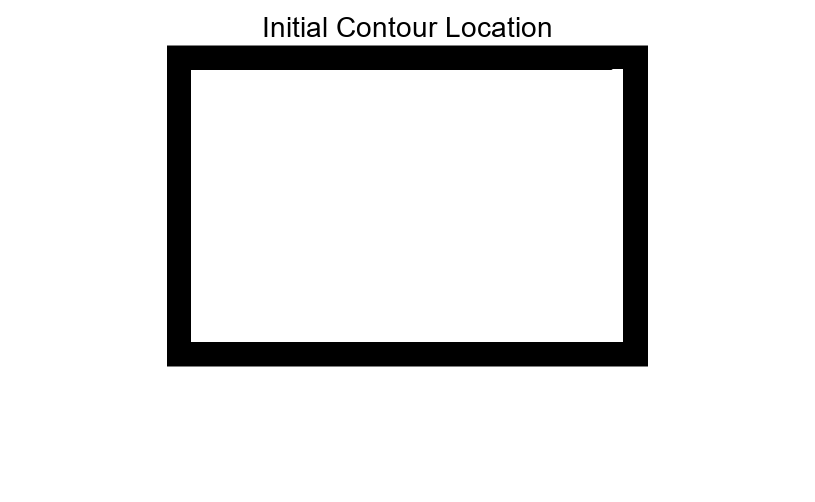

%%指定关注对象周围的初始轮廓。显示该轮廓
mask = zeros(size(I));%初始化一个与I图像一样大小的值都为0的图像mask
%mask(Y1:Y2,X1:X2),(X1,Y1)为矩形左上角，（X1，Y2）为矩形右下角
mask(25:end-25,25:end-25) = 1;%调整mask区域，x轴为（25~X_max_size-25),y轴为（25~Y_max_size-25)的区域赋值为1（纯白)
figure,imshow(mask)%显示mask图像
title('Initial Contour Location')%添加标签

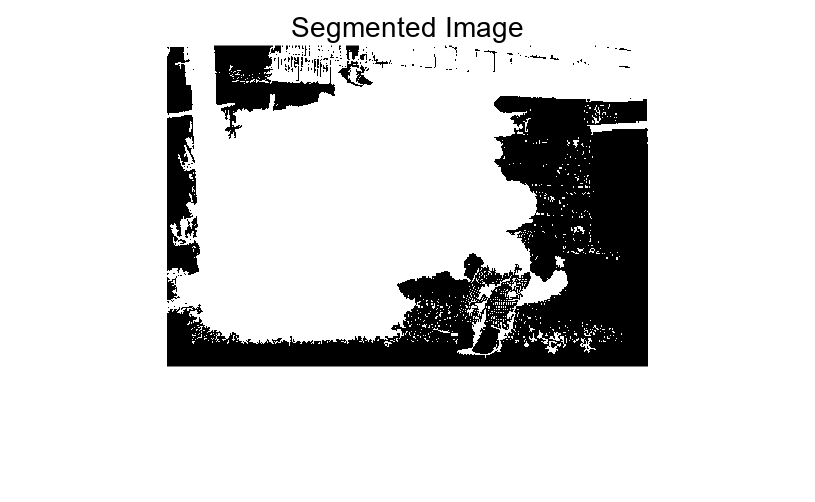

%%使用默认方法的300次迭代对图像进行分割
bw = activecontour(I,mask,300);%调用activecontour函数

figure, imshow(bw);%显示分割图像
title('Segmented Image');%添加标签

I=imread('im1.jpg');
image_size=size(I);
dimension=numel(image_size);
if dimension==2
    Ig = I; 
end
if dimension==3
    Ig = im2gray(I);
end
;

function [seg]= Dog(I)  % Difference of Gussian 
    dog=fspecial('gaussian',3,0.45)-fspecial('gaussian',3,0.5);
    Idiff = conv2(I,dog,'same');
     seg=imbinarize(Idiff,0.0001);
end
function [seg] = Can(I)
    ICanny=edge(I,'Canny');
    seg = ICanny;
end
function [seg] =BY(I)
    gc=fspecial('gaussian',9,1);
    gs=fspecial('gaussian',9,1.5);
    IaBY=conv2(I(:,:,3),gc,'same')-conv2(mean(I(:,:,1:2),3),gs,'same'); %blue-on, yellow-of
    seg=imbinarize(IaBY,0.01);
end